% Topic is deep learning: classification of fruits

%  Path to train set directory
trainDatasetPath = fullfile('C:\Users\OMBATI\Desktop\matlab\project-one\COURSE WORK\train');

% Create an imageDatastore using the path
imds = imageDatastore(trainDatasetPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

img = readimage(imds, 1);
size(img)

ans =    100   100     3



% Number of images per category
tbl = countEachLabel(imds);

% Adjust the number of images in the training set to be balanced
% Determine the smallest amount of images in a category
minSetCount = min(tbl{:, 2}); 

% Limit the number of images to reduce the time it takes
% Run this example.
maxNumImages = 100;
minSetCount = min(maxNumImages, minSetCount);

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Each set now has exactly the same number of images.
countEachLabel(imds)

ans = 33×2 table
          Label           Count
    __________________    _____

    Apple Braeburn         100 
    Apple Granny Smith     100 
    Apricot                100 
    Avocado                100 
    Banana                 100 
    Blueberry              100 
    Cactus fruit           100 
    Cantaloupe             100 
    Cherry                 100 
    Clementine             100 
    Corn                   100 
    Cucumber Ripe          100 
    Grape Blue             100 
    Kiwi                   100 
    Lemon                  100 
    Limes                  100 


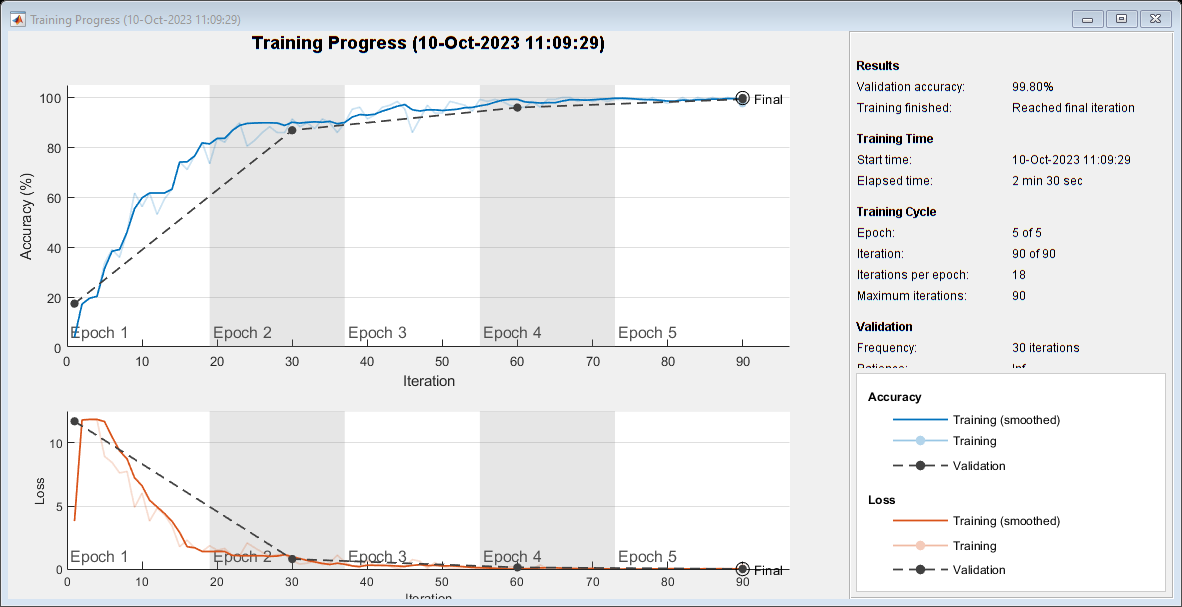


% Specify Training and Validation Sets
numTrainFiles = 70;
[imdsTrain, imdsValidation] = splitEachLabel(imds, numTrainFiles, 'randomize');






% Define the convolutional neural network architecture

layers = [
    imageInputLayer([100 100 3])
    
    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(33) % Change to 33 output units
    softmaxLayer
    classificationLayer];

% Initialize arrays to store readable images and labels
readableImages = {};
readableLabels = [];

% Loop through the imageDatastore and store readable images and labels
for i = 1:numel(imdsTrain.Files)
    try
        img = readimage(imdsTrain, i);
        % If the image is successfully read, store it and its label
        readableImages{end+1} = img;
        readableLabels(end+1) = imdsTrain.Labels(i);
    catch
        fprintf('Error reading image: %s\n', imdsTrain.Files{i});
    end
end

% Create a cell array of file paths for the readable images
readableImagePaths = imdsTrain.Files(~cellfun('isempty', readableImages));

% Create an imageDatastore from the readable images and labels
readableImdsTrain = imageDatastore(readableImagePaths, ...
    'Labels', categorical(readableLabels), 'IncludeSubfolders', true);

% Update the options to use the new imageDatastore
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 5, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', imdsValidation, ... % Use imdsValidation
    'ValidationFrequency', 30, ...
    'Verbose', false, ...
    'Plots', 'training-progress');


net = trainNetwork(imdsTrain, layers, options);


% Inspect the first layer
net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'imageinput'
                 InputSize: [100 100 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [1×1×3 single]



% Inspect the last layer
net.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'classoutput'
         Classes: [33×1 categorical]
      OutputSize: 33

   Hyperparameters
    LossFunction: 'crossentropyex'



% Number of class names for ImageNet classification task
numel(net.Layers(end).ClassNames)

ans = 33

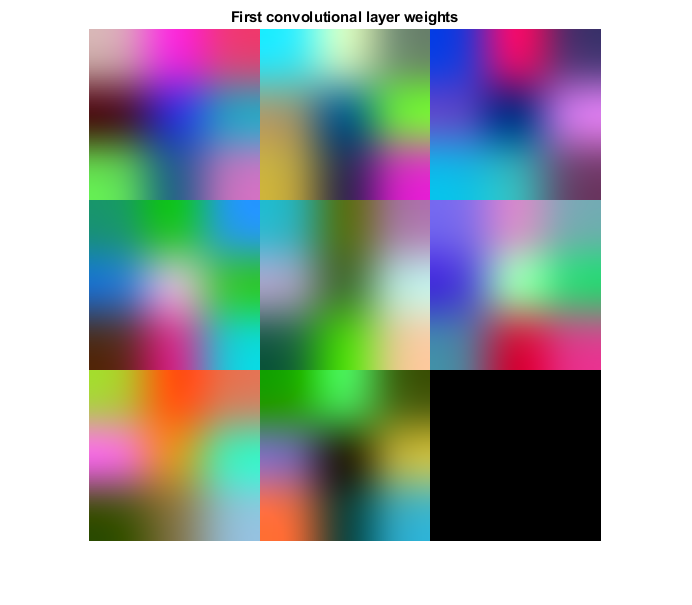


% Get the network weights for the second convolutional layer
w1 = net.Layers(2).Weights;

% Scale and resize the weights for visualization
w1 = mat2gray(w1);
w1 = imresize(w1,5); 

% Display a montage of network weights. 

figure
montage(w1)
title('First convolutional layer weights')





% Classify validation data
YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;



% Calculate the confusion matrix
confMat = confusionmat(YValidation, YPred);

% Calculate the sum of each row (actual class)
rowSum = sum(confMat, 2);

% Divide each element in the confusion matrix by the corresponding row sum
confMatPercentage = confMat ./ rowSum;

% Display the confusion matrix in percentage form
disp("Confusion Matrix (Percentage Form):");

Confusion Matrix (Percentage Form):


disp(confMatPercentage);

  Columns 1 through 16

    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0



% Calculate accuracy
accuracy = sum(YPred == YValidation) / numel(YValidation);
disp(['Validation accuracy: ', num2str(accuracy)]);

Validation accuracy: 0.99798
